maxIterations = 500;
gridSize = 1000;
xlim = [-0.748766713922161, -0.748766707771757];
ylim = [ 0.123640844894862,  0.123640851045266]; 


x = gpuArray.linspace(xlim(1),xlim(2),gridSize);
%x = linspace(xlim(1),xlim(2),gridSize);
y = gpuArray.linspace(ylim(1),ylim(2),gridSize);
%y = linspace(ylim(1),ylim(2),gridSize);
whos x y

  Name      Size              Bytes  Class       Attributes

  x         1x1000                4  gpuArray              
  y         1x1000                4  gpuArray              




[xGrid,yGrid] = meshgrid(x,y);
z0 = complex(xGrid,yGrid);
count = ones(size(z0),'gpuArray');

tic;
z = z0;
for n = 0:maxIterations
    z = z.*z + z0;
    inside = abs(z) <= 2;
    count = count + inside;
end
count = log(count);
toc

Elapsed time is 0.082229 seconds.


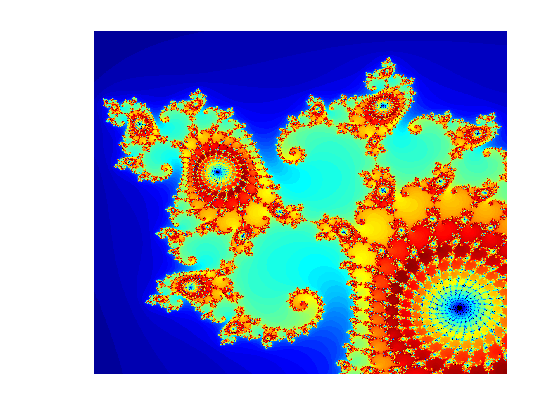


imagesc(x,y,count)
colormap([jet();flipud(jet());0 0 0]);
axis off